slide 4 page 19

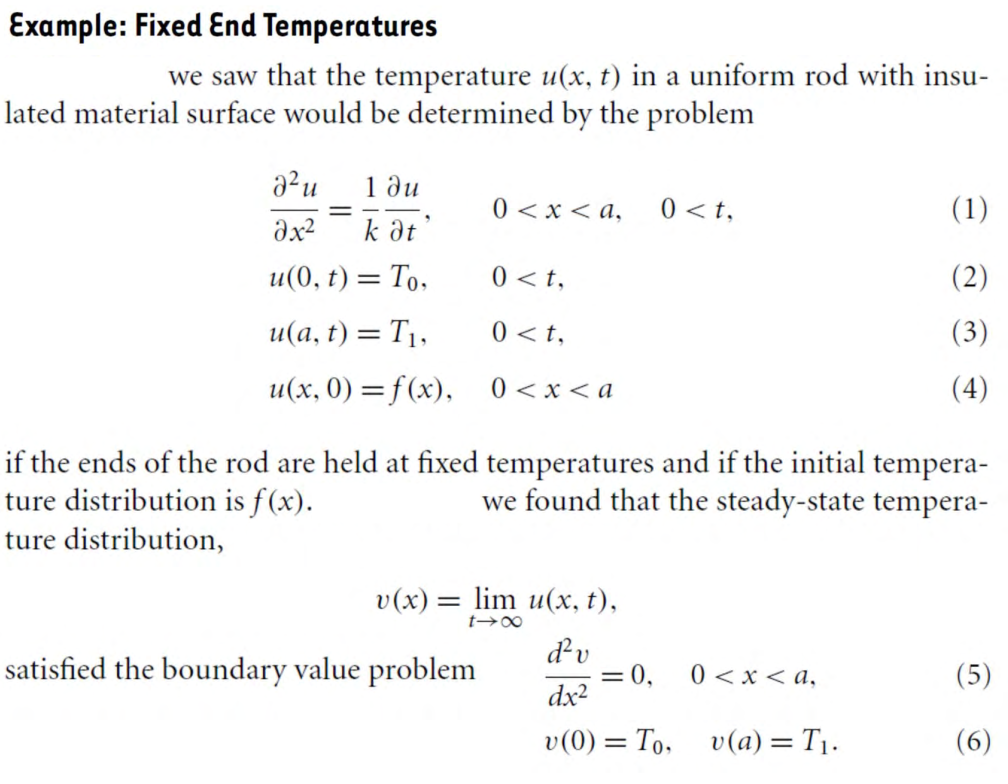

clear
clf
clc 
syms x v(x) a T0 T1 D
assume(a,'positive')
SteadyS= D*diff(v,x,2)==0

$$SteadyS(x) = \text{D}\,\frac{\partial^{2}}{\partial x^{2}}v\left(x\right)=0$$

C0=v(0)==T0

$$C0 = v\left(0\right)=T_{0}$$

Ca=v(a)==T1

$$Ca = v\left(a\right)=T_{1}$$

v(x)= dsolve (SteadyS,[C0 Ca])

$$v(x) = T_{0}-\frac{x\,\left(T_{0}-T_{1}\right)}{a}$$

**Transiwnt w(x,t)=u(x,t) - v(x)**

**Separation part**

syms t w(x,t)
assume([a D],"positive")
HeatEq = diff(w,t)== D*diff(w,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}w\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}w\left(x,t\right)$$

BC0 = w(0,t) ==0

$$BC0 = w\left(0,t\right)=0$$

BCL = w(a,t)==0

$$BCL = w\left(a,t\right)=0$$

syms T(t) X(x)
SepVar = subs(HeatEq, w(x,t),X(x)*T(t));
SepVar = SepVar/(D*X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

var = children(SepVar);
BCx0 = subs(BC0,w(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

BCxa = subs (BCL,w(a,t),X(a))

$$BCxa = X\left(a\right)=0$$

syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda)= dsolve(eqX,BCx0)

$$X(x, lambda) = -C_{1}\,\sin\left(\lambda \,x\right)$$

constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda)= subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

sln = X(a,lambda) ==0;

**Finding lambda**

[lambda,parameters,conditions] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{a}$$

syms b_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);
ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),['sin' 'exp'])

$$ustruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{a^{2}}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)$$

**Fourier series part**

syms x t n b(n) phi(x)
assume(n,'integer')
phi(x)= 0-v(x);
ft0=subs(ustruct(x,0,n),sym("b_n"),1)

$$ft0 = \sin\left(\frac{\pi \,n\,x}{a}\right)$$

b(n) = simplify(2/a*int(phi(x)*ft0,x,[0 a]))

$$b(n) = -\frac{2\,\left(T_{0}-{\left(-1\right)}^{n}\,T_{1}\right)}{n\,\pi }$$

D = 0.1

D = 0.1000

N= 1

N = 1

T0 = 20

T0 = 20

T1=80

T1 = 80

a =1

a = 1

tau = 6

tau = 6

v(x) = subs(v,sym(["a" "T0" "T1"]),[a T0 T1])

$$v(x) = 60\,x+20$$

b(n) = subs(b,sym(["T0" "T1"]),[T0 T1])

$$b(n) = \frac{2\,\left(80\,{\left(-1\right)}^{n}-20\right)}{n\,\pi }$$

heatStruct = ustruct

$$heatStruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{a^{2}}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)$$

heatStructEmb(x,t,n) = subs(heatStruct,sym(["b_n" "a" "D"]),[b a D]);

**Solution**

heatSolN = v(x)+simplify(symsum(heatStructEmb,n,1,N))

$$heatSolN(x, t) = 60\,x-\frac{200\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{10}}\,\sin\left(\pi \,x\right)}{\pi }+20$$

heatStructEmb(x,t,n) = v(x)+symsum(heatStructEmb,n,1,inf)

$$heatStructEmb(x, t, n) = 60\,x+\frac{2\,\left(\sum_{n=1}^{\infty }\frac{\sin\left(\pi \,n\,x\right)\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{10}}\,\left(80\,{\left(-1\right)}^{n}-20\right)}{n}\right)}{\pi }+20$$

**3D plot**

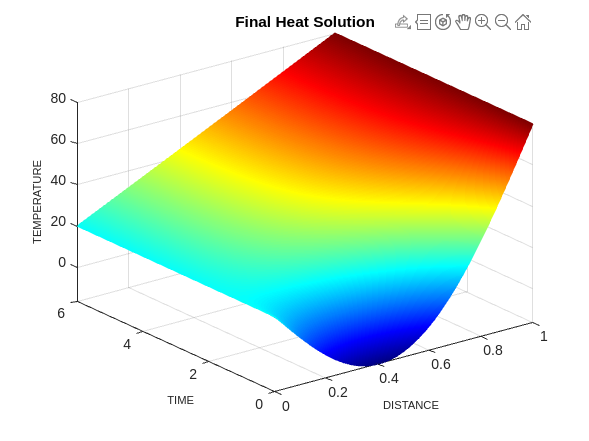

figure 
colormap jet
fsurf(heatSolN,[0 a 0 tau],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('DISTANCE','FontSize',8);
ylabel('TIME','Fontsize',8);
zlabel('TEMPERATURE','FontSize',8)

slide4 page34  

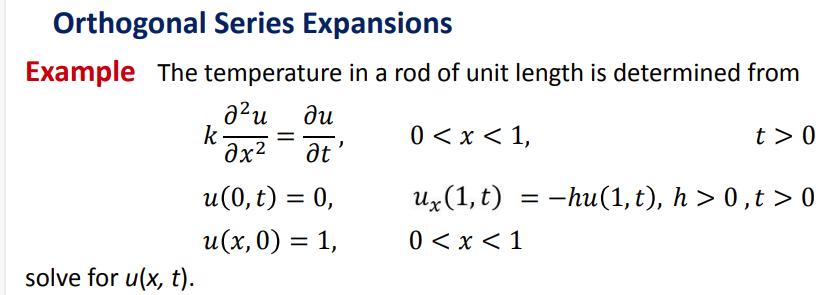

**Separation part**

clear
clf
clc
syms x t u(x,t) L D h
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0;
syms  T(t) X(x)
Sepvar = subs(HeatEq,u(x,t),X(x)*T(t));
BCx0 = subs(BC0,u(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

Sepvar = Sepvar/(D*X(x)*T(t));
var = children(Sepvar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0);
constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

DxL(x,lambda) = diff(X,x);
sln = DxL(L,lambda) == -h*X(L,lambda)

$$sln = C_{2}\,\lambda \,\cos\left(L\,\lambda \right)=-C_{2}\,h\,\sin\left(L\,\lambda \right)$$

var = children(sln);
syms b_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);
ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["sin" "exp"])

$$ustruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)$$

lambda = var(2)*lambda/var(1)

$$lambda = -\frac{h\,\sin\left(L\,\lambda \right)}{\cos\left(L\,\lambda \right)}$$

**Plot "tan x = -x" and display "x"**

clf
L = 4

L = 4

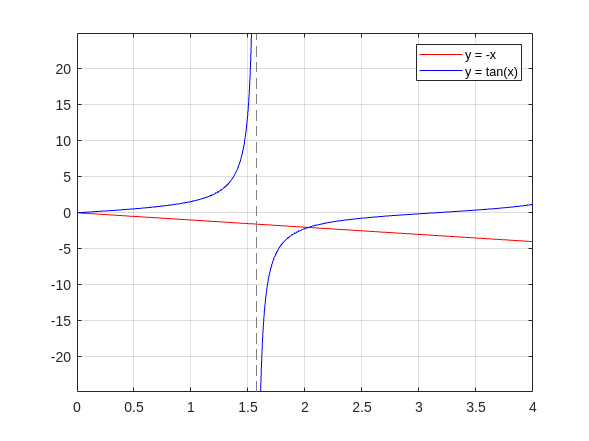

fplot(@(x) -x,[0,L],'r');
grid on, hold on
fplot(@tan,[0,L],'b')
legend('y = -x','y = tan(x)')

x = linspace(0,L);
fun = @(x) tan(x)+x;
f = fun(x);
I = find(sign(f(2:end))-sign(f(1:end-1)));
r = zeros([1 length(I)]);
for n = 1:length(I)
    r(n) = vpa(fzero(fun, x([I(n),I(n)+1])));
end

**Orthogonal Series Expansions**

syms x t n b(n) phi(x)
assume(n,"integer")
phi(x) = 1;
ft0 = subs(ustruct(x,0,n),sym(["b_n" "L"]),[1 L])

$$ft0 = \sin\left(\lambda \,x\right)$$

bnum(n) = simplify(int(phi(X)*ft0,x,[0 L]));
bden(n) = simplify(int(ft0^2,x,[0 L]));
[Num,Den] = numden(bnum);
Den = subs(Den,sym("lambda"),lambda);
bnum(n) = subs(Num/Den,sym("L"),L);
[Num,Den] = numden(bden);
Den = subs(Den,sym("lambda"),lambda);
bden(n) = subs(Num/Den,sym("L"),L);
D = 1

D = 1

solution = subs(ustruct,"D",D)

$$solution(x, t, n) = b_{n}\,{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)$$

b(n) = simplify(bnum/bden)

$$b(n) = \frac{8\,{\sin\left(2\,\lambda \right)}^{2}}{8\,\lambda -\sin\left(8\,\lambda \right)}$$

heatstructEmb(x,t,n) = subs(ustruct,sym(["b_n" "L" "D"]),[b L D])

$$heatstructEmb(x, t, n) = \frac{8\,{\sin\left(2\,\lambda \right)}^{2}\,{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)}{8\,\lambda -\sin\left(8\,\lambda \right)}$$

Emb = 0;
for i = 2:length(I)
    Emb = Emb+subs(heatstructEmb(x,t,i),sym("lambda"),r(i));
end
heatSolN(x,t) = Emb

$$heatSolN(x, t) = -\frac{8\,{\sin\left(\frac{2284178260934781}{562949953421312}\right)}^{2}\,{\mathrm{e}}^{-\frac{5217470327727040476995935517961\,t}{1267650600228229401496703205376}}\,\sin\left(\frac{2284178260934781\,x}{1125899906842624}\right)}{\sin\left(\frac{2284178260934781}{140737488355328}\right)-\frac{2284178260934781}{140737488355328}}$$

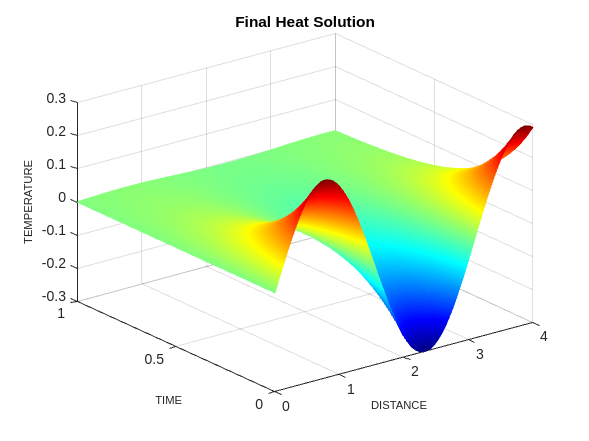

figure
colormap jet
fsurf(heatSolN,[0 L 0 L/4],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('DISTANCE','FontSize',8);
ylabel('TIME','FontSize',8);
zlabel('TEMPERATURE','FontSize',8);

**Heat profile at different times**

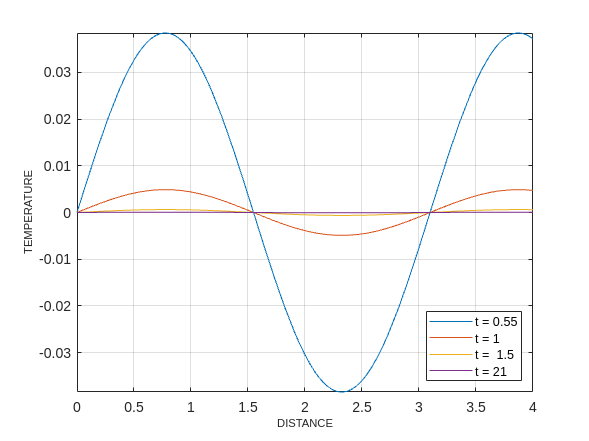

clf
tm = [0.5 1 1.5 2];
for i = 1:length(tm)
    sn  = matlabFunction(heatSolN(x,tm(i)));
    fplot(sn,[0 L])
    grid on, hold on
end
xlabel('DISTANCE','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)
legend('t = 0.55','t = 1','t =  1.5','t = 21','Location','southeast')

**Heat profile at various times**

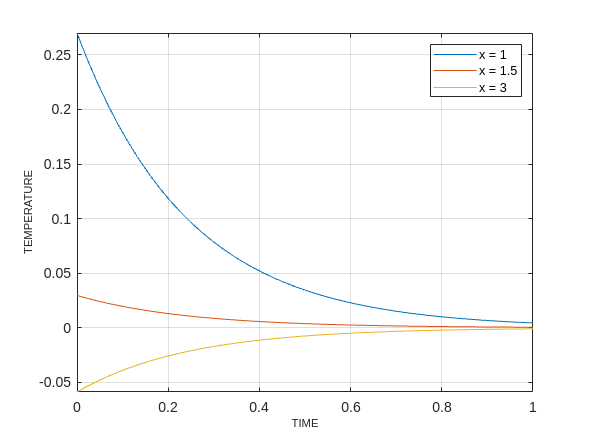

clf
dst = [1 1.5 3];
for i = 1:length(dst)
    sn  = matlabFunction(heatSolN(dst(i),t));
    fplot(sn,[0 1])
    grid on, hold on
end
xlabel('TIME','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)
legend('x = 1','x = 1.5','x = 3','Location','northeast')